# Problem 1

addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
mu = 132712440017.99;
AU = 149598000;

## Part a)

r1 = 1.83*AU, lam1 = deg2rad(43.7), del1 = deg2rad(33.9)

r1 = 273764340

lam1 = 0.7627

del1 = 0.5917

r2 = 3.15*AU, lam2 = deg2rad(62.4), del2 = deg2rad(48.2)

r2 = 471233700

lam2 = 1.0891

del2 = 0.8412


r1_I = r1*[cos(lam1)*cos(del1);sin(lam1)*cos(del1);sin(del1)]

r1_I = 	1.0e+08 *

    1.6428
    1.5699
    1.5269


r2_I = r2*[cos(lam2)*cos(del2);sin(lam2)*cos(del2);sin(del2)]

r2_I = 	1.0e+08 *

    1.4552
    2.7835
    3.5129



hhat = cross(r1_I,r2_I)/norm(cross(r1_I,r2_I))

hhat =     0.2869
   -0.8051
    0.5191


inc = acos(hhat(3)), inc_deg = rad2deg(inc)

inc = 1.0250

inc_deg = 58.7283

% om = pi-asin(hhat(1)/sin(inc))
om = acos(-hhat(2)/sin(inc)), om_deg = rad2deg(om)

om = 0.3423

om_deg = 19.6138

TA = acos(r1_I'*r2_I/r1/r2), TA_deg = rad2deg(TA)

TA = 0.3487

TA_deg = 19.9802

c = sqrt(r1^2 + r2^2 - 2*r1*r2*cos(TA))

c = 2.3350e+08

s = 1/2 * (r1+r2+c)

s = 4.8925e+08

amin = s/2

amin = 2.4463e+08

alphamin = 2*asin(sqrt(s/2/amin))

alphamin = 3.1416

betamin = 2*asin(sqrt((s-c)/2/amin))

betamin = 1.6163



TOFmin = sqrt(amin^3/mu) * ((alphamin-sin(alphamin))-(betamin-sin(betamin)))

TOFmin = 2.6511e+07

TOFmin_month = TOFmin/24/3600/30

TOFmin_month = 10.2282


TOFpar = 1/3 * sqrt(2/mu)*(s^(3/2)-(s-c)^(3/2))

TOFpar = 8.7110e+06

TOfpar_month = TOFpar/24/3600/30

TOfpar_month = 3.3607


TOF = 3.26*30*24*3600

TOF = 8449920

[a,alpha,beta] = bisection(TOF,amin,c,mu,'1H',.01)

a = -3.0128e+09

alpha = 0.5624

beta = 0.4092

p = 4*abs(a)*(s-r1)*(s-r2)/c^2 * sinh((alpha+beta)/2)^2

p = 2.1897e+08

e = sqrt(1-p/a)

e = 1.0357

dH = alpha-beta

dH = 0.1533

rp = a*(1-e)

rp = 1.0757e+08


ts1 = acos(1/e * (p/r1 - 1)), tsD_deg = rad2deg(ts1)

ts1 = 1.7653

tsD_deg = 101.1423

ts2 = ts1+TA, tsA_deg = rad2deg(ts2)

ts2 = 2.1140

tsA_deg = 121.1225


f = 1-abs(a)/r1 * (cosh(dH)-1)

f = 0.8705

g = r2*r1/sqrt(mu*p)*sin(TA)

g = 8.1772e+06


v1_I = (r2_I-f*r1_I)/g

v1_I =     0.3080
   17.3284
   26.7062



romhat = [cos(om);sin(om);0]

romhat =     0.9420
    0.3357
         0



th1 = acos(dot(romhat,r1_I/r1)), th1_deg = rad2deg(th1)

th1 = 0.7109

th1_deg = 40.7342

w = th1 - ts1, w_deg = rad2deg(w)

w = -1.0543

w_deg = -60.4081


fdot = -sqrt(mu*abs(a))/r1/r2 * sinh(dH)

fdot = -2.3851e-08

gdot = 1-abs(a)/r2*(cosh(dH)-1)

gdot = 0.9247


v2_I = fdot*r1_I + gdot*v1_I

v2_I =    -3.6334
   12.2801
   21.0547



H1 = conicanom(ts1,e)

H1 = 0.3249

H1 = conicanom(ts2,e)

H1 = 0.4782


[TOF2,dt1,dt2] = timeofflight(ts1,ts2,a,e,r1,mu)

TOF2 = 8.4499e+06

dt1 = 7.9694e+06

dt2 = 1.6419e+07


dt1_month = dt1/3600/24/30

dt1_month = 3.0746

dt2_month = dt2/3600/24/30

dt2_month = 6.3346

TOFmonth2 = dt2_month-dt1_month

TOFmonth2 = 3.2600


tsinf = acos(-1/e)

tsinf = 2.8783

plotorbit(a,e,-tsinf*.8,tsinf*.8,0,'k')
hold on
plotorbit(a,e,ts1,ts2,0,'b')
plotpos(a,e,ts1,'r',0,1)
plotpos(a,e,ts2,'r',0,1)
plotpos(a,e,w,'k',0,.000001) % AOP

v1 = sqrt(mu*(2/r1-1/a)) 

v1 = 31.8369

v2 = sqrt(mu*(2/r2-1/a))

v2 = 24.6435

gamma1 = acos(sqrt(mu*p)/r1/v1), gamma1_deg = rad2deg(gamma1)

gamma1 = 0.9040

gamma1_deg = 51.7930

gamma2 = acos(sqrt(mu*p)/r2/v2), gamma2_deg = rad2deg(gamma2)

gamma2 = 1.0881

gamma2_deg = 62.3412

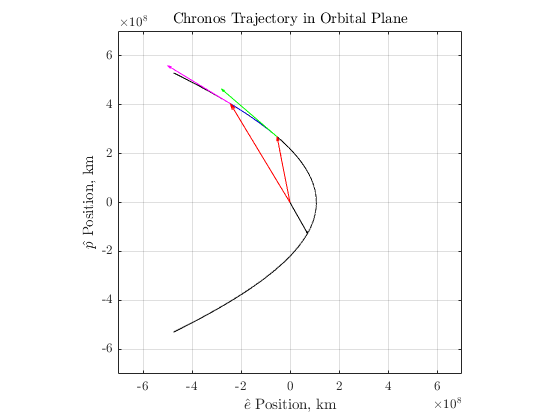

iCr1 = [cos(ts1) -sin(ts1); sin(ts1) cos(ts1)];
iCr2 = [cos(ts2) -sin(ts2); sin(ts2) cos(ts2)];
v1_ep = iCr1*[sin(gamma1);cos(gamma1)];
v2_ep = iCr2*[sin(gamma2);cos(gamma2)];
plotvel(a,e,ts1,v1_ep,'g',0,0,3e8)
plotvel(a,e,ts2,v2_ep,'m',0,0,3e8)
xlim([-7 7]*1e8)
ylim([-7 7]*1e8)
title('Chronos Trajectory in Orbital Plane')
xlabel('$\hat{e}$ Position, km')
ylabel('$\hat{p}$ Position, km')